R1 = 100e3;  
R2 = 47e3;  
R3 = 1e3;  
R4 = 1e3;  
R5 = 1e3;
R6 = 1e3;    
R7 = 10e3;  
R8 = 1e3;  
R9 = 1e3;
C1 = 0.1e-6; 
C2 = 0.1e-6;
k    = 1 + R7/R9;
Vin = 1;                    

s    = tf('s');
G    = k / ((R1*C1*s + 1)*(R2*C2*s + 1));
Sysf = feedback(G, 1)


Sysf =
 
              11
  ---------------------------
  4.7e-05 s^2 + 0.0147 s + 12
 
Continuous-time transfer function.


%% 2. Respuesta al escalón: parámetros obtenidos por simulación
t2 = (0:1e-5:0.1)';                % grilla de 10 µs durante 100 ms
y2 = step(Sysf, t2);
info2 = stepinfo(y2, t2);          % por defecto: banda del 2 % y tr del 10 % al 90 %
y_inf = dcgain(Sysf);              % valor en estado estacionario

% Valores con las fórmulas del punto 1c, para comparar
[wn_v, zeta_v] = damp(Sysf);
wn2 = wn_v(1);
zeta2 = zeta_v(1);
PO_f = 100*exp(-pi*zeta2/sqrt(1 - zeta2^2));
Tp_f = pi/(wn2*sqrt(1 - zeta2^2));
Ts_f = 4/(zeta2*wn2);
tr_f = 1.8/wn2;

T2 = table(["PO [%]"; "Tp [ms]"; "Ts [ms]"; "tr [ms]"; "y(inf)"], ...
           [PO_f; Tp_f*1e3; Ts_f*1e3; tr_f*1e3; k/(1 + k)], ...
           [info2.Overshoot; info2.PeakTime*1e3; info2.SettlingTime*1e3; info2.RiseTime*1e3; y2(end)], ...
           'VariableNames', {'Parametro', 'Formula', 'Simulacion'})

T2 = 5×3 table
    Parametro    Formula    Simulacion
    _________    _______    __________

    "PO [%]"       35.97       35.97  
    "Tp [ms]"     6.5384        6.54  
    "Ts [ms]"     25.578      22.174  
    "tr [ms]"     3.5623      2.6395  
    "y(inf)"     0.91667     0.91667  



% Chequeo con caso conocido: sin ceros, el PO simulado tiene que coincidir con la fórmula
fprintf('PO: fórmula = %.3f %% | simulación = %.3f %%\n', PO_f, info2.Overshoot);

PO: fórmula = 35.970 % | simulación = 35.970 %


fprintf('y(final) = %.4f (k/(1+k) = %.4f)\n', y2(end), k/(1 + k));

y(final) = 0.9167 (k/(1+k) = 0.9167)


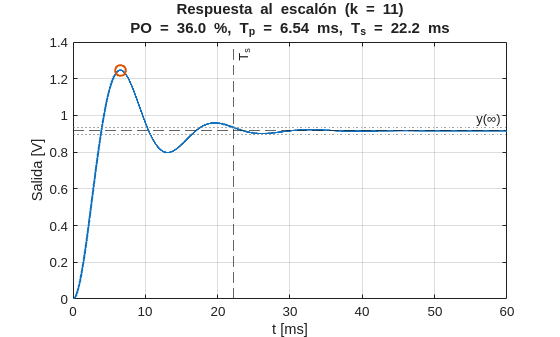


% Gráfico con los parámetros marcados
figure
plot(t2*1e3, y2, 'LineWidth', 1.5); hold on
yline(y_inf, '--', 'y(\infty)');
yline(y_inf*[0.98 1.02], ':', 'Color', [0.5 0.5 0.5]);   % banda del 2 %
plot(info2.PeakTime*1e3, info2.Peak, 'o', 'MarkerSize', 8, 'LineWidth', 1.5)
xline(info2.SettlingTime*1e3, '--', 'T_s');
grid on; xlabel('t [ms]'); ylabel('Salida [V]'); xlim([0 60])
title({'Respuesta al escalón (k = 11)', sprintf('PO = %.1f %%, T_p = %.2f ms, T_s = %.1f ms', info2.Overshoot, info2.PeakTime*1e3, info2.SettlingTime*1e3)})
guardar("Respuesta_Escalon_Completa")

%% 3. Error en estado estacionario por simulación (escalón y rampa)
E = feedback(1, G);                 % E(s)/Entrada(s) = 1/(1 + G(s))
t3 = (0:1e-5:0.2)';                 % 200 ms

e_esc  = step(E, t3);               % escalón unitario
e_ramp = lsim(E, t3, t3);           % rampa unitaria: r(t) = t

% Escalón: tiene que tender a 1/(1+k)
ess_esc = 1/(1 + k);
fprintf('Escalón: e(final) simulado = %.5f | calculado 1/(1+k) = %.5f\n', e_esc(end), ess_esc);

Escalón: e(final) simulado = 0.08333 | calculado 1/(1+k) = 0.08333



% Rampa: no se estabiliza, crece sin límite
fprintf('Rampa: e(0,1 s) = %.4f V, e(0,2 s) = %.4f V -> crece sin límite\n', interp1(t3, e_ramp, 0.1), e_ramp(end));

Rampa: e(0,1 s) = 0.0095 V, e(0,2 s) = 0.0178 V -> crece sin límite



% Chequeo con caso conocido: para t grande es una recta de pendiente 1/(1+k)
tramo = t3 >= 0.15;                 % últimos 50 ms, cuando ya pasó el transitorio
coef  = polyfit(t3(tramo), e_ramp(tramo), 1);
c_teo = (R1*C1 + R2*C2)*k/(1 + k)^2;
fprintf('Rampa: pendiente = %.5f V/s (teórica %.5f) | ordenada = %.5f V (teórica %.5f)\n', coef(1), 1/(1 + k), coef(2), c_teo);

Rampa: pendiente = 0.08333 V/s (teórica 0.08333) | ordenada = 0.00112 V (teórica 0.00112)


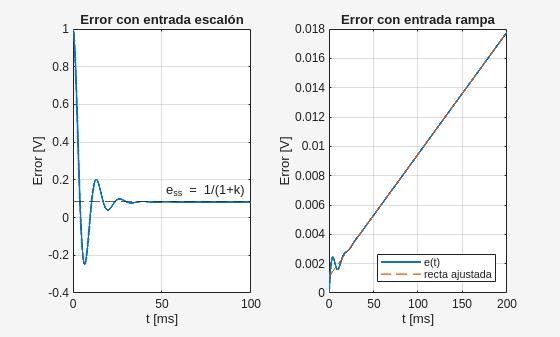


figure
tiledlayout(1, 2)

nexttile
plot(t3*1e3, e_esc, 'LineWidth', 1.5); hold on
yline(ess_esc, '--', 'e_{ss} = 1/(1+k)');
grid on; xlabel('t [ms]'); ylabel('Error [V]'); xlim([0 100])
title('Error con entrada escalón')

nexttile
plot(t3*1e3, e_ramp, 'LineWidth', 1.5); hold on
plot(t3*1e3, polyval(coef, t3), '--', 'LineWidth', 1)
grid on; xlabel('t [ms]'); ylabel('Error [V]')
legend('e(t)', 'recta ajustada', 'Location', 'southeast')
title('Error con entrada rampa')
guardar("Error_Escalon_Rampa")

modelo = 'circuito_TP1';

load_system(modelo);  
guardar_modelo(modelo, "B_5a_modelo")

out = sim(modelo);

t_sim = out.y_sim.Time;
y_sim = squeeze(out.y_sim.Data);
[t_sim, iu] = unique(t_sim);  
y_sim = y_sim(iu);

t    = (0:1e-5:t_sim(end))';
y_ft = Vin * step(Sysf, t);
y_sc = interp1(t_sim, y_sim, t);

err = abs(y_sc - y_ft);
[err_max, i_max] = max(err);
fprintf('Error máximo: %.3e  (en t = %.2f)\n', err_max, t(i_max)*1e3);

Error máximo: 2.196e-06  (en t = 8.18)


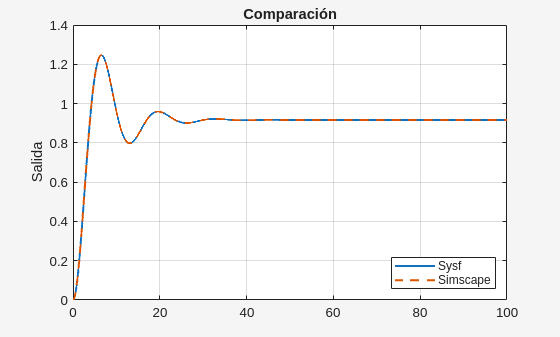


figure
plot(t*1e3, y_ft, 'LineWidth', 1.5); 
hold on
plot(t_sim*1e3, y_sim, '--', 'LineWidth', 1.5)
grid on; 
ylabel('Salida')
legend('Sysf', 'Simscape', 'Location', 'southeast')
title('Comparación');  
guardar("B_5b_comparacion")

%5c
%% 5c. Señal de error: salida de U1A
E = feedback(1, G)              % E(s)/Entrada(s) = 1/(1 + G(s))


E =
 
  4.7e-05 s^2 + 0.0147 s + 1
  ---------------------------
  4.7e-05 s^2 + 0.0147 s + 12
 
Continuous-time transfer function.


e_ss = 1/(1 + k);               % error en estado estacionario del punto 3

% Error por función de transferencia
e_ft = Vin * step(E, t);

% Error simulado (salida de U1A)
t_e   = out.e_sim.Time;
e_sim = squeeze(out.e_sim.Data);
[t_e, iu] = unique(t_e); e_sim = e_sim(iu);
e_sc  = interp1(t_e, e_sim, t);

% Comparación
err_e = abs(e_sc - e_ft);
[err_e_max, i_e] = max(err_e);
fprintf('Error máximo en e(t): %.3e V (en t = %.2f ms)\n', err_e_max, t(i_e)*1e3);

Error máximo en e(t): 2.196e-06 V (en t = 8.18 ms)



% Chequeos con valores conocidos
fprintf('e(0):     FT = %.4f   Simscape = %.4f   (esperado 1)\n', e_ft(1), e_sc(1));

e(0):     FT = 1.0000   Simscape = 1.0000   (esperado 1)


fprintf('e(final): FT = %.5f  Simscape = %.5f  (punto 3: 1/(1+k) = %.5f)\n', ...
        e_ft(end), e_sc(end), e_ss);

e(final): FT = 0.08333  Simscape = 0.08333  (punto 3: 1/(1+k) = 0.08333)


fprintf('max |e_sim - (Vin - y_sim)| = %.3e V  (U1A tiene que restar exacto)\n', ...
        max(abs(e_sc - (Vin - y_sc))));

max |e_sim - (Vin - y_sim)| = 2.498e-16 V  (U1A tiene que restar exacto)


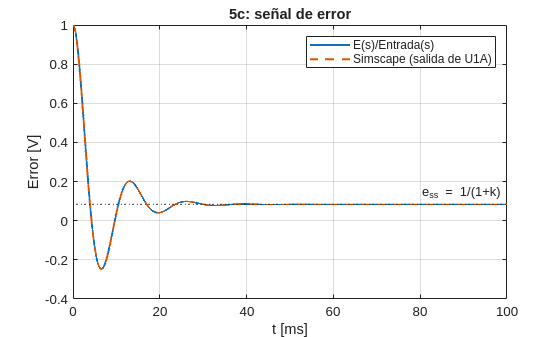


figure
plot(t*1e3, e_ft, 'LineWidth', 1.5); hold on
plot(t_e*1e3, e_sim, '--', 'LineWidth', 1.5)
yline(e_ss, ':', 'e_{ss} = 1/(1+k)', 'LineWidth', 1)
grid on; xlabel('t [ms]'); ylabel('Error [V]')
legend('E(s)/Entrada(s)', 'Simscape (salida de U1A)', 'Location', 'northeast')
title('5c: señal de error');  guardar("B_5c_error")

%% 5d. Barrido de k (parte 1: simular y comparar)
% Pares R7/R9 del punto 4 (cambialos si elegiste otros)
k_lista  = [1, 3.2, 5.7, 34];
R7_lista = [1e3, 2.2e3, 4.7e3, 33e3];
R9_lista = [1e12, 1e3, 1e3, 1e3];        % k = 1: R9 abierto
etiq     = {'1k / abierto', '2.2k / 1k', '4.7k / 1k', '33k / 1k'};

R7_nom = R7;  R9_nom = R9;               % guardo los valores de la Fig. 1

n = numel(k_lista);
k_ef  = zeros(1, n);
err5d = zeros(1, n);
Y_ft  = zeros(numel(t), n);              % una columna por caso
Y_sc  = zeros(numel(t), n);

figure
tiledlayout(2, 2)
for i = 1:n
    R7 = R7_lista(i);
    R9 = R9_lista(i);
    k_ef(i) = 1 + R7/R9;

    % Modelo por función de transferencia
    G_i    = k_ef(i) / ((R1*C1*s + 1)*(R2*C2*s + 1));
    Sysf_i = feedback(G_i, 1);
    Y_ft(:, i) = Vin * step(Sysf_i, t);

    % Simulación (el modelo toma R7 y R9 del workspace)
    out_i = sim(modelo);
    t_i = out_i.y_sim.Time;
    y_i = squeeze(out_i.y_sim.Data);
    [t_i, iu] = unique(t_i); y_i = y_i(iu);
    Y_sc(:, i) = interp1(t_i, y_i, t);

    err5d(i) = max(abs(Y_sc(:, i) - Y_ft(:, i)));

    % Chequeo con valor conocido: y(final) = k/(1+k)
    fprintf('k = %-4g (%s): k_ef = %.4f | y(final) sim = %.4f, teo = %.4f | error máx = %.2e V\n', ...
        k_lista(i), etiq{i}, k_ef(i), Y_sc(end, i), k_ef(i)/(1 + k_ef(i)), err5d(i));

    nexttile
    plot(t*1e3, Y_ft(:, i), 'LineWidth', 1.5); hold on
    plot(t*1e3, Y_sc(:, i), '--', 'LineWidth', 1.5)
    grid on; xlabel('t [ms]'); ylabel('Salida [V]'); xlim([0 60])
    title(sprintf('k = %g  (R7/R9 = %s)', k_lista(i), etiq{i}))
    legend('Sysf', 'Simscape', 'Location', 'southeast')
end

k = 1    (1k / abierto): k_ef = 1.0000 | y(final) sim = 0.5000, teo = k = 3.2  (2.2k / 1k): k_ef = 3.2000 | y(final) sim = 0.7619, teo = k = 5.7  (4.7k / 1k): k_ef = 5.7000 | y(final) sim = 0.8507k = 34   (33k / 1k): k_ef = 34.0000 | y(final) sim = 0.9714, teo = 0.9714 | error máx = 1.12e-05 V


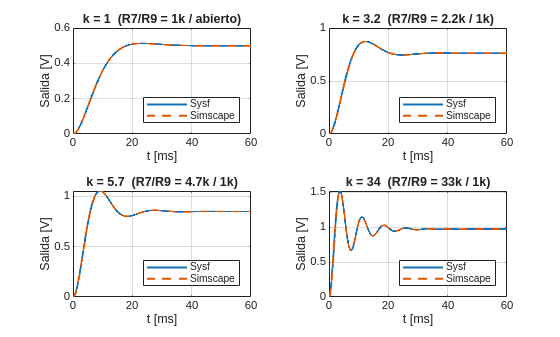


R7 = R7_nom;  R9 = R9_nom;  guardar("B_5d_barrido_k")

%% 5d. Barrido de k (parte 2: parámetros medidos y tabla)
tau1 = R1*C1;
tau2 = R2*C2;

[wn, zeta, PO_ft, Tp_ft, Ts_ft, PO_sc, Tp_sc, Ts_sc, ...
 yinf_teo, yinf_sc, ess_teo, ess_sc] = deal(zeros(n, 1));

for i = 1:n
    % Fórmulas del punto 1c
    wn(i)   = sqrt((1 + k_ef(i))/(tau1*tau2));
    zeta(i) = (tau1 + tau2)/(2*sqrt((1 + k_ef(i))*tau1*tau2));

    % Medidos sobre la curva de Sysf
    info_ft  = stepinfo(Y_ft(:, i), t);
    PO_ft(i) = info_ft.Overshoot;
    Tp_ft(i) = info_ft.PeakTime;
    Ts_ft(i) = info_ft.SettlingTime;

    % Medidos sobre la simulación de Simscape
    info_sc  = stepinfo(Y_sc(:, i), t);
    PO_sc(i) = info_sc.Overshoot;
    Tp_sc(i) = info_sc.PeakTime;
    Ts_sc(i) = info_sc.SettlingTime;

    % Valor final y error en estado estacionario
    yinf_teo(i) = k_ef(i)/(1 + k_ef(i));
    ess_teo(i)  = 1/(1 + k_ef(i));
    yinf_sc(i)  = Y_sc(end, i);
    ess_sc(i)   = Vin - Y_sc(end, i);

    % Chequeo con caso conocido: PO de la fórmula de 2do orden
    PO_formula = 100*exp(-pi*zeta(i)/sqrt(1 - zeta(i)^2));
    fprintf('k = %-4g: PO fórmula = %.3f %% | stepinfo(Sysf) = %.3f %% | stepinfo(Simscape) = %.3f %%\n', ...
            k_lista(i), PO_formula, PO_ft(i), PO_sc(i));
end

k = 1   : PO fórmula = 2.594 % | stepinfo(Sysf) = 2.594 % | stepinfo(Simscape) = 2.594 %
k = 3.2 : PO fórmula = 14.538 % | stepinfo(Sysf) = 14.538 % | stepinfo(Simscape) = 14.538 %
k = 5.7 : PO fórmula = 23.940 % | stepinfo(Sysf) = 23.940 % | stepinfo(Simscape) = 23.940 %
k = 34  : PO fórmula = 56.051 % | stepinfo(Sysf) = 56.051 % | stepinfo(Simscape) = 56.052 %



% Tabla del punto 4 con las columnas medidas sobre la simulación
T5d = table(k_lista', string(etiq'), k_ef', wn, zeta, ...
            PO_ft, PO_sc, Tp_ft, Tp_sc, Ts_ft, Ts_sc, ...
            yinf_teo, yinf_sc, ess_teo, ess_sc, ...
    'VariableNames', {'k', 'R7_R9', 'k_ef', 'wn_rad_s', 'zeta', ...
                      'PO_FT', 'PO_sim', 'Tp_FT_s', 'Tp_sim_s', 'Ts_FT_s', 'Ts_sim_s', ...
                      'yinf_teo', 'yinf_sim', 'ess_teo', 'ess_sim'})

T5d = 4×15 table
     k         R7_R9         k_ef    wn_rad_s     zeta      PO_FT     PO_sim    Tp_FT_s    Tp_sim_s    Ts_FT_s     Ts_sim_s    yinf_teo    yinf_sim    ess_teo     ess_sim 
    ___    ______________    ____    ________    _______    ______    ______    _______    ________    ________    ________    ________    ________    ________    ________

      1    "1k / abierto"      1      206.28     0.75809     2.594     2.594    0.02335    0.02335     0.027434    0.027434        0.5         0.5          0.5         0.5
    3.2    "2.2k / 1k"       3.2      298.93     0.52313    14.538    14.538    0.01233    0.01233     0.025832    0.025832     0.7619      0.7619       0.2381      0.2381
    5.7    "4.7k / 1k"       5.7      377.56     0.41419     23.94     23.94    0.00914    0.00914     0.022256    0.022256    0.85075     0.85075      0.14925     0.14925
     34    "33k / 1k"         34      862.95     0.18122    56.051    56.052     0.0037     0.0037     0.023278    0.02327

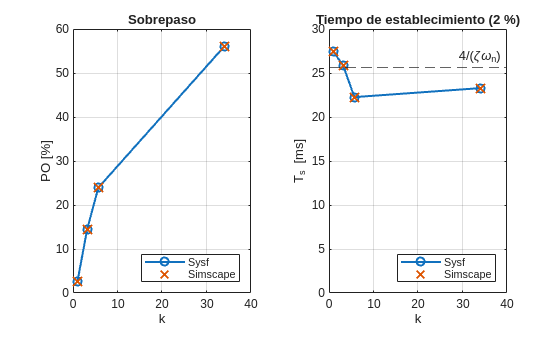


% Gráfico: cómo cambian PO y Ts con k
figure
tiledlayout(1, 2)

nexttile
plot(k_lista, PO_ft, 'o-', 'LineWidth', 1.5); hold on
plot(k_lista, PO_sc, 'x', 'MarkerSize', 10, 'LineWidth', 1.5)
grid on; xlabel('k'); ylabel('PO [%]'); title('Sobrepaso')
legend('Sysf', 'Simscape', 'Location', 'southeast')

nexttile
plot(k_lista, Ts_ft*1e3, 'o-', 'LineWidth', 1.5); hold on
plot(k_lista, Ts_sc*1e3, 'x', 'MarkerSize', 10, 'LineWidth', 1.5)
yline(4/(zeta(1)*wn(1))*1e3, '--', '4/(\zeta\omega_n)')
grid on; xlabel('k'); ylabel('T_s [ms]'); ylim([0 30])
title('Tiempo de establecimiento (2 %)')
legend('Sysf', 'Simscape', 'Location', 'southeast');  guardar("B_5d_PO_Ts")

%% 6a. Op-amps ideales vs TL081 (régimen lineal), k = 11 y k = 34
modelo_tl = 'circuito_TP1_TL081';
load_system(modelo_tl)

k6   = [11, 34];
R7_6 = [10e3, 33e3];          % R9 = 1k en los dos casos
A0   = 2e5;                   % ganancia de lazo abierto del TL081

% Vectores donde guardo los resultados (uno por cada k)
PO_id6   = zeros(2, 1);   PO_tl6   = zeros(2, 1);
Tp_id6   = zeros(2, 1);   Tp_tl6   = zeros(2, 1);
Ts_id6   = zeros(2, 1);   Ts_tl6   = zeros(2, 1);
yinf_id6 = zeros(2, 1);   yinf_tl6 = zeros(2, 1);
dif6     = zeros(2, 1);

figure
tiledlayout(2, 2)
for i = 1:2
    R7 = R7_6(i);
    R9 = 1e3;

    % Simulación con op-amps ideales
    out_id = sim(modelo);
    [t_id, iu] = unique(out_id.y_sim.Time);
    y_id = squeeze(out_id.y_sim.Data);
    y_id = y_id(iu);

    % Simulación con TL081
    out_tl = sim(modelo_tl);
    [t_tl, iu] = unique(out_tl.y_sim.Time);
    y_tl = squeeze(out_tl.y_sim.Data);
    y_tl = y_tl(iu);

    % Las paso a la misma grilla para poder restarlas
    y_id_u = interp1(t_id, y_id, t);
    y_tl_u = interp1(t_tl, y_tl, t);
    dif6(i) = max(abs(y_tl_u - y_id_u));

    % Parámetros con stepinfo
    info_id = stepinfo(y_id_u, t);
    info_tl = stepinfo(y_tl_u, t);
    PO_id6(i) = info_id.Overshoot;      PO_tl6(i) = info_tl.Overshoot;
    Tp_id6(i) = info_id.PeakTime;       Tp_tl6(i) = info_tl.PeakTime;
    Ts_id6(i) = info_id.SettlingTime;   Ts_tl6(i) = info_tl.SettlingTime;
    yinf_id6(i) = y_id_u(end);          yinf_tl6(i) = y_tl_u(end);

    % Chequeo con valor conocido: valor final con ganancia A0 finita
    L0 = (A0/(A0 + 2)) * (A0/(A0 + 1)) * (k6(i)*A0/(k6(i) + A0));
    fprintf('k = %d: y(final) ideal = %.6f | TL081 = %.6f | teórico con A0 finita = %.6f\n', k6(i), yinf_id6(i), yinf_tl6(i), L0/(1 + L0));

    % Curvas superpuestas
    nexttile
    plot(t*1e3, y_id_u, 'LineWidth', 1.5); hold on
    plot(t*1e3, y_tl_u, '--', 'LineWidth', 1.5)
    grid on; xlabel('t [ms]'); ylabel('Salida [V]'); xlim([0 60])
    title(sprintf('k = %d', k6(i)))
    legend('op-amp ideal', 'TL081', 'Location', 'southeast')

    % Diferencia (en el gráfico de al lado no se ve)
    nexttile
    plot(t*1e3, (y_tl_u - y_id_u)*1e3, 'LineWidth', 1.2)
    grid on; xlabel('t [ms]'); ylabel('y_{TL081} - y_{ideal} [mV]'); xlim([0 60])
    title(sprintf('Diferencia, k = %d (máx %.2f mV)', k6(i), dif6(i)*1e3))
end

k = 11: y(final) ideal = 0.916667 | TL081 = 0.916661 | teórico con A0 finita = 0.916661
k = 34: y(final) ideal = 0.971429 | TL081 = 0.971424 | teórico con A0 finita = 0.971423


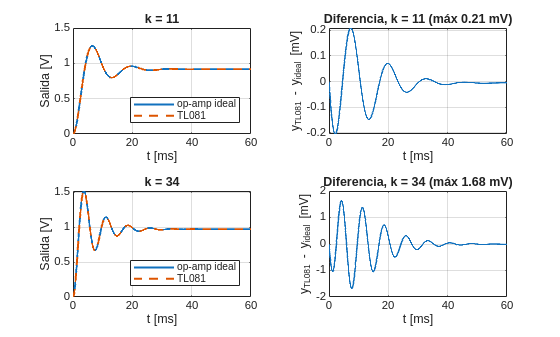


R7 = R7_nom;  R9 = R9_nom;  guardar("B_6a_TL081")      % vuelvo a los valores de la Fig. 1


% Tabla de comparación
T6a = table(k6', PO_id6, PO_tl6, PO_tl6 - PO_id6, Tp_id6*1e3, Tp_tl6*1e3, Ts_id6*1e3, Ts_tl6*1e3, (Ts_tl6 - Ts_id6)*1e6, dif6*1e3);
T6a.Properties.VariableNames = {'k', 'PO_ideal', 'PO_TL081', 'dPO', 'Tp_ideal_ms', 'Tp_TL081_ms', 'Ts_ideal_ms', 'Ts_TL081_ms', 'dTs_us', 'dif_max_mV'};
T6a

T6a = 2×10 table
    k     PO_ideal    PO_TL081      dPO       Tp_ideal_ms    Tp_TL081_ms    Ts_ideal_ms    Ts_TL081_ms    dTs_us    dif_max_mV
    __    ________    ________    ________    ___________    ___________    ___________    ___________    ______    __________

    11      35.97      35.991     0.021349       6.54           6.54          22.175         22.177       2.4368     0.20859  
    34     56.052        56.2      0.14884        3.7            3.7          23.278         23.296       17.829      1.6795  


%% 6b. Amplitud de escalón a partir de la cual se recorta la salida (k = 34)
Vmax = 8.5;                     % excursión máxima del TL081
k_b  = 34;
tau1 = R1*C1;
tau2 = R2*C2;
den_b = conv([tau1 1], [tau2 1]) + [0 0 k_b];   % (tau1 s + 1)(tau2 s + 1) + k

% Salida de cada op-amp por cada voltio de escalón (op-amps ideales)
H_U2A = tf(k_b, den_b);                         % salida del circuito
H_U1A = tf(conv([tau1 1], [tau2 1]), den_b);    % error e(t)
H_U3A = tf([tau2 1], den_b);                    % tensión en C1

v_U2A = step(H_U2A, t);
v_U1A = step(H_U1A, t);
v_U3A = step(H_U3A, t);

pico    = [max(abs(v_U2A)), max(abs(v_U1A)), max(abs(v_U3A))];
A_lim   = Vmax ./ pico;
nombres = {'U2A (salida)', 'U1A (error)', 'U3A (V_{C1})'};

% Chequeo con valor conocido: el enunciado dice 1,52 V por voltio
fprintf('Pico de la salida: %.4f V por voltio (enunciado: 1,52)\n', pico(1));

Pico de la salida: 1.5159 V por voltio (enunciado: 1,52)



for j = 1:3
    fprintf('%-14s: pico = %.4f V/V -> satura con escalones mayores a %.2f V\n', nombres{j}, pico(j), A_lim(j));
end

U2A (salida)  : pico = 1.5159 V/V -> satura con escalones mayores a 5.61 V
U1A (error)   : pico = 1.0000 V/V -> satura con escalones mayores a 8.50 V
U3A (V_{C1})  : pico = 0.1130 V/V -> satura con escalones mayores a 75.19 V


A_b = min(A_lim);
fprintf('La salida empieza a recortarse con escalones mayores a %.2f V\n', A_b);

La salida empieza a recortarse con escalones mayores a 5.61 V


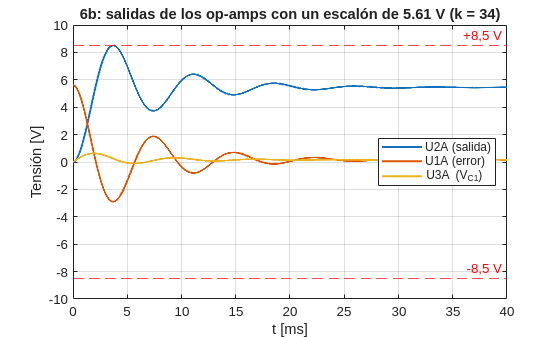


% Gráfico: las tres salidas justo en el límite
figure
plot(t*1e3, A_b*v_U2A, 'LineWidth', 1.5); hold on
plot(t*1e3, A_b*v_U1A, 'LineWidth', 1.5)
plot(t*1e3, A_b*v_U3A, 'LineWidth', 1.5)
yline(Vmax, 'r--', '+8,5 V');
yline(-Vmax, 'r--', '-8,5 V');
grid on; xlabel('t [ms]'); ylabel('Tensión [V]'); xlim([0 40]); ylim([-10 10])
legend(nombres, 'Location', 'east')
title(sprintf('6b: salidas de los op-amps con un escalón de %.2f V (k = 34)', A_b));  guardar("B_6b_nodos")

%% 6c. Escalones de 5 V y 7 V con el TL081 (k = 34)
R7 = 33e3;
R9 = 1e3;
k_c = 1 + R7/R9;
Sysf_34 = feedback(k_c / ((R1*C1*s + 1)*(R2*C2*s + 1)), 1);
y_lin = step(Sysf_34, t);              % respuesta lineal por cada voltio

amps   = [5, 7];
Y6c    = zeros(numel(t), 2);
pico6c = zeros(2, 1);
PO6c   = zeros(2, 1);
Tp6c   = zeros(2, 1);
Ts6c   = zeros(2, 1);
yfin6c = zeros(2, 1);

for i = 1:2
    Vin = amps(i);
    out_c = sim(modelo_tl);
    [t_c, iu] = unique(out_c.y_sim.Time);
    y_c = squeeze(out_c.y_sim.Data);
    y_c = y_c(iu);
    Y6c(:, i) = interp1(t_c, y_c, t);

    info = stepinfo(Y6c(:, i), t);
    pico6c(i) = info.Peak;
    PO6c(i)   = info.Overshoot;
    Tp6c(i)   = info.PeakTime;
    Ts6c(i)   = info.SettlingTime;
    yfin6c(i) = Y6c(end, i);

    % Comparación con lo que predice Sysf (sistema lineal)
    fprintf('A = %d V: pico = %.3f V (lineal: %.3f V) | valor final = %.4f V (lineal: %.4f V)\n', amps(i), pico6c(i), amps(i)*max(y_lin), yfin6c(i), amps(i)*y_lin(end));

    % ¿Durante cuánto tiempo la salida queda clavada en 8,5 V?
    recortada = Y6c(:, i) >= Vmax - 1e-3;
    if any(recortada)
        fprintf('         salida recortada entre %.2f ms y %.2f ms\n', t(find(recortada, 1))*1e3, t(find(recortada, 1, 'last'))*1e3);
    else
        fprintf('         sin recorte\n');
    end
end

A = 5 V: pico = 7.587 V (lineal: 7.580 V) | valor final = 4.8571 V (lineal: A = 7 V: pico = 8.500 V (lineal: 10.611 V) | valor final = 6.8000 V (lineal: 6.8000 V)


         salida recortada entre 2.51 ms y 6.81 ms



Vin = 1;  R7 = R7_nom;  R9 = R9_nom;     % vuelvo a la Fig. 1 y al escalón de 1 V

T6c = table(amps', pico6c, PO6c, Tp6c*1e3, Ts6c*1e3, yfin6c);
T6c.Properties.VariableNames = {'A_V', 'pico_V', 'PO', 'Tp_ms', 'Ts_ms', 'yfinal_V'};
T6c

T6c = 2×6 table
    A_V    pico_V      PO      Tp_ms    Ts_ms     yfinal_V
    ___    ______    ______    _____    ______    ________

     5     7.5868      56.2     3.7     23.296     4.8571 
     7        8.5    25.001    2.51     24.967        6.8 


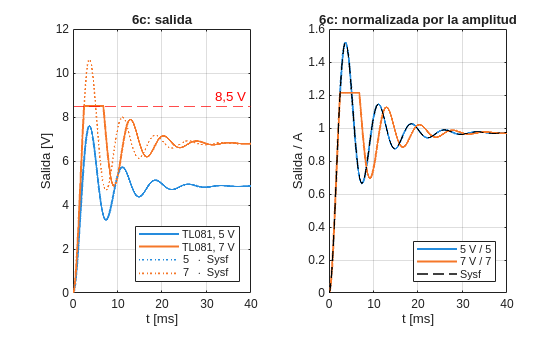


% Gráficos
c = lines(2);                          % mismo color para cada amplitud
figure
tiledlayout(1, 2)

% Izquierda: salida en volts, junto con lo que predeciría Sysf
nexttile
plot(t*1e3, Y6c(:, 1), 'Color', c(1, :), 'LineWidth', 1.5); hold on
plot(t*1e3, Y6c(:, 2), 'Color', c(2, :), 'LineWidth', 1.5)
plot(t*1e3, 5*y_lin, ':', 'Color', c(1, :), 'LineWidth', 1.2)
plot(t*1e3, 7*y_lin, ':', 'Color', c(2, :), 'LineWidth', 1.2)
yline(Vmax, 'r--', '8,5 V');
grid on; xlabel('t [ms]'); ylabel('Salida [V]'); xlim([0 40])
legend('TL081, 5 V', 'TL081, 7 V', '5 \cdot Sysf', '7 \cdot Sysf', 'Location', 'southeast')
title('6c: salida')

% Derecha: dividida por la amplitud. Si el sistema fuera lineal, coincidirían todas
nexttile
plot(t*1e3, Y6c(:, 1)/5, 'Color', c(1, :), 'LineWidth', 1.5); hold on
plot(t*1e3, Y6c(:, 2)/7, 'Color', c(2, :), 'LineWidth', 1.5)
plot(t*1e3, y_lin, 'k--', 'LineWidth', 1)
grid on; xlabel('t [ms]'); ylabel('Salida / A'); xlim([0 40])
legend('5 V / 5', '7 V / 7', 'Sysf', 'Location', 'southeast')
title('6c: normalizada por la amplitud');  guardar("B_6c_escalones")

%% 7a. Tolerancias: qué combinación da el mayor y el menor sobrepaso (k = 11)
nom  = [R1, C1, R2, C2, R7_nom, R9_nom];      % valores de la Fig. 1
tol  = [0.05, 0.10, 0.05, 0.10, 0.05, 0.05];  % resistores ±5 %, capacitores ±10 %
comp = {'R1', 'C1', 'R2', 'C2', 'R7', 'R9'};

% Fórmulas del punto 1c en función de v = [R1 C1 R2 C2 R7 R9]   (1 + k = 2 + R7/R9)
zeta_de = @(v) (v(1)*v(2) + v(3)*v(4)) / (2*sqrt((2 + v(5)/v(6)) * v(1)*v(2)*v(3)*v(4)));
wn_de   = @(v) sqrt((2 + v(5)/v(6)) / (v(1)*v(2)*v(3)*v(4)));
PO_de   = @(z) 100*exp(-pi*z/sqrt(1 - z^2));

% Chequeo con caso conocido: sin tolerancias tiene que dar el PO nominal
fprintf('Nominal: zeta = %.4f, wn = %.1f rad/s, PO = %.3f %% (6a, ideal: %.3f %%)\n', zeta_de(nom), wn_de(nom), PO_de(zeta_de(nom)), PO_id6(1));

Nominal: zeta = 0.3095, wn = 505.3 rad/s, PO = 35.970 % (6a, ideal: 35.970 %)



% Todas las combinaciones de extremos: cada componente en -1 (mínimo) o +1 (máximo)
signos = 2*(dec2bin(0:63) - '0') - 1;         % matriz de 64 filas x 6 columnas

PO_c = zeros(64, 1);
Ts_c = zeros(64, 1);
for j = 1:64
    v = nom .* (1 + signos(j, :) .* tol);     % valores de esta combinación
    z = zeta_de(v);
    PO_c(j) = PO_de(z);
    Ts_c(j) = 4/(z*wn_de(v));
end

[PO_max, j_max] = max(PO_c);
[PO_min, j_min] = min(PO_c);

% Desviación de cada componente (en %) en los dos casos extremos
T7a = array2table(100*[signos(j_max, :).*tol; signos(j_min, :).*tol], 'VariableNames', comp, 'RowNames', {'PO max', 'PO min'});
T7a.PO = [PO_max; PO_min];
T7a

T7a = 2×7 table
              R1    C1     R2    C2     R7    R9      PO  
              __    ___    __    ___    __    __    ______

    PO max    -5    -10     5     10     5    -5     39.44
    PO min     5     10    -5    -10    -5     5    31.662


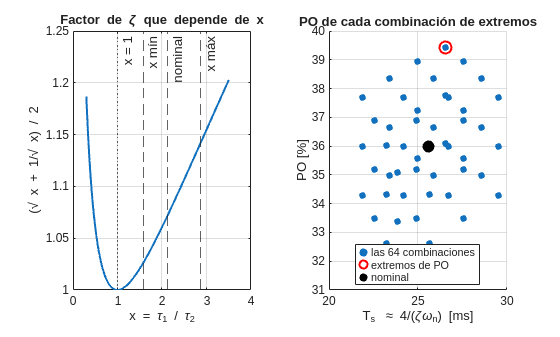


% Rango de x = tau1/tau2 que permiten las tolerancias
x_nom = (R1*C1)/(R2*C2);
x_min = x_nom * (0.95*0.90)/(1.05*1.10);
x_max = x_nom * (1.05*1.10)/(0.95*0.90);

figure
tiledlayout(1, 2)

nexttile
x = linspace(0.3, 3.5, 400);
plot(x, (sqrt(x) + 1./sqrt(x))/2, 'LineWidth', 1.5); hold on
xline(1, ':', 'x = 1');
xline([x_min, x_nom, x_max], '--', {'x mín', 'nominal', 'x máx'});
grid on; xlabel('x = \tau_1 / \tau_2'); ylabel('(\surd x + 1/\surd x) / 2')
title('Factor de \zeta que depende de x')

nexttile
scatter(Ts_c*1e3, PO_c, 25, 'filled'); hold on
scatter(Ts_c([j_max, j_min])*1e3, PO_c([j_max, j_min]), 80, 'r', 'LineWidth', 1.5)
scatter(4/(zeta_de(nom)*wn_de(nom))*1e3, PO_de(zeta_de(nom)), 80, 'k', 'filled')
grid on; xlabel('T_s \approx 4/(\zeta\omega_n) [ms]'); ylabel('PO [%]')
legend('las 64 combinaciones', 'extremos de PO', 'nominal', 'Location', 'best')
title('PO de cada combinación de extremos');  guardar("B_7a_tolerancias")

%% 7b. Simulación de los casos extremos junto con el nominal (op-amps ideales)
casos   = {'nominal', 'PO máximo', 'PO mínimo'};
sig_cas = [zeros(1, 6); signos(j_max, :); signos(j_min, :)];   % desviación de cada caso

PO7     = zeros(3, 1);
Tp7     = zeros(3, 1);
Ts7     = zeros(3, 1);
PO7_teo = zeros(3, 1);
Y7      = zeros(numel(t), 3);

for c7 = 1:3
    v = nom .* (1 + sig_cas(c7, :) .* tol);
    R1 = v(1);  C1 = v(2);  R2 = v(3);  C2 = v(4);  R7 = v(5);  R9 = v(6);

    out7 = sim(modelo);
    [t7, iu] = unique(out7.y_sim.Time);
    y7 = squeeze(out7.y_sim.Data);
    y7 = y7(iu);
    Y7(:, c7) = interp1(t7, y7, t);

    info = stepinfo(Y7(:, c7), t);
    PO7(c7) = info.Overshoot;
    Tp7(c7) = info.PeakTime;
    Ts7(c7) = info.SettlingTime;

    % Chequeo con valor conocido: el PO simulado tiene que coincidir con la fórmula
    PO7_teo(c7) = PO_de(zeta_de(v));
    fprintf('%-10s: PO sim = %.2f %% (fórmula %.2f %%) | Tp = %.2f ms | Ts = %.2f ms\n', casos{c7}, PO7(c7), PO7_teo(c7), Tp7(c7)*1e3, Ts7(c7)*1e3);
end

nominal   : PO sim = 35.97 % (fórmula PO máximo : PO sim = 39.44 % (fórmula 39.44PO mínimo : PO sim = 31.66 % (fórmula 31.66 %) | Tp = 6.86 ms | Ts = 22.62 ms



% Vuelvo a los valores de la Fig. 1
R1 = nom(1);  C1 = nom(2);  R2 = nom(3);  C2 = nom(4);  R7 = nom(5);  R9 = nom(6);

fprintf('Rango de PO: %.2f %% a %.2f %% (%.2f puntos)\n', min(PO7), max(PO7), max(PO7) - min(PO7));

Rango de PO: 31.66 % a 39.44 % (7.78 puntos)


fprintf('Rango de Ts: %.2f ms a %.2f ms (%.2f ms)\n', min(Ts7)*1e3, max(Ts7)*1e3, (max(Ts7) - min(Ts7))*1e3);

Rango de Ts: 22.17 ms a 25.91 ms (3.74 ms)


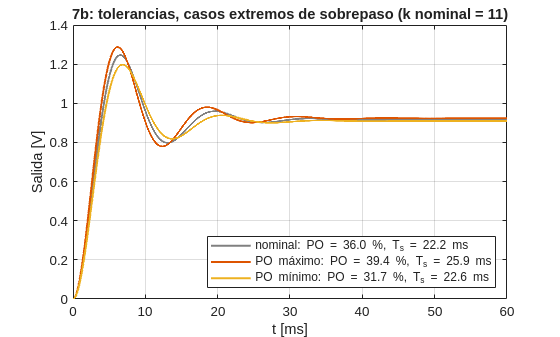


% Los tres casos en una única figura
figure
plot(t*1e3, Y7(:, 1), 'Color', [0.5 0.5 0.5], 'LineWidth', 1.5); hold on
plot(t*1e3, Y7(:, 2), 'LineWidth', 1.5)
plot(t*1e3, Y7(:, 3), 'LineWidth', 1.5)
grid on; xlabel('t [ms]'); ylabel('Salida [V]'); xlim([0 60])
leyendas = cell(1, 3);
for c7 = 1:3
    leyendas{c7} = sprintf('%s: PO = %.1f %%, T_s = %.1f ms', casos{c7}, PO7(c7), Ts7(c7)*1e3);
end
legend(leyendas, 'Location', 'southeast')
title('7b: tolerancias, casos extremos de sobrepaso (k nominal = 11)');  guardar("B_7b_extremos")

%% 7c (parte 1). Tolerancias vs TL081: ¿qué efecto domina?
dPO_tol = max(PO7) - min(PO7);              % 7b: tolerancias
dTs_tol = max(Ts7) - min(Ts7);
dPO_op  = abs(PO_tl6(1) - PO_id6(1));       % 6a: TL081 con k = 11
dTs_op  = abs(Ts_tl6(1) - Ts_id6(1));

fprintf('Variación de PO: tolerancias %.2f puntos | TL081 %.4f puntos | cociente %.0f\n', dPO_tol, dPO_op, dPO_tol/dPO_op);

Variación de PO: tolerancias 7.78 puntos | TL081 0.0213 puntos | cociente 364


fprintf('Variación de Ts: tolerancias %.3f ms | TL081 %.5f ms | cociente %.0f\n', dTs_tol*1e3, dTs_op*1e3, dTs_tol/dTs_op);

Variación de Ts: tolerancias 3.736 ms | TL081 0.00244 ms | cociente 1533


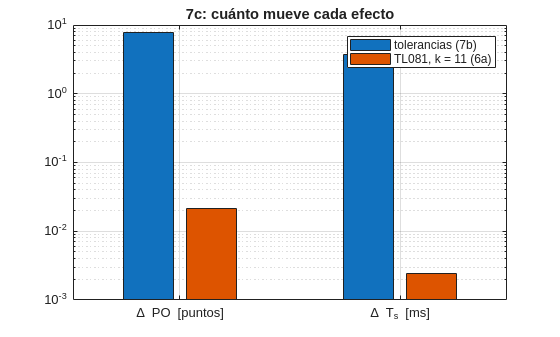


% Comparación en escala logarítmica (si no, la barra del TL081 no se ve)
figure
bar([dPO_tol, dPO_op; dTs_tol*1e3, dTs_op*1e3])
set(gca, 'YScale', 'log', 'XTickLabel', {'\Delta PO [puntos]', '\Delta T_s [ms]'})
grid on
legend('tolerancias (7b)', 'TL081, k = 11 (6a)', 'Location', 'northeast')
title('7c: cuánto mueve cada efecto');  guardar("B_7c_comparacion")


% Ubicación de los polos
tau1 = R1*C1;
tau2 = R2*C2;
wb = 2*pi*15;                  % polo del TL081 a lazo abierto [rad/s]
wT = A0*wb;                    % producto ganancia-ancho de banda [rad/s]

polos    = [1/tau1, 1/tau2, wn_de(nom), wb, wT/11, wT/2, wT];
nombres7 = {'planta: 1/\tau_1', 'planta: 1/\tau_2', 'lazo cerrado: \omega_n (k = 11)', 'TL081 a lazo abierto (15 Hz)', 'U2A realimentado: \omega_T/k', 'U1A realimentado: \omega_T/2', 'U3A realimentado: \omega_T'};

for j = 1:numel(polos)
    fprintf('%-34s: %10.4g rad/s\n', nombres7{j}, polos(j));
end

planta: 1/\tau_1                  :        100 rad/s
planta: 1/\tau_2                  :      212.8 rad/s
lazo cerrado: \omega_n (k = 11)   :      505.3 rad/s
TL081 a lazo abierto (15 Hz)      :      94.25 rad/s
U2A realimentado: \omega_T/k      :  1.714e+06 rad/s
U1A realimentado: \omega_T/2      :  9.425e+06 rad/s
U3A realimentado: \omega_T        :  1.885e+07 rad/s


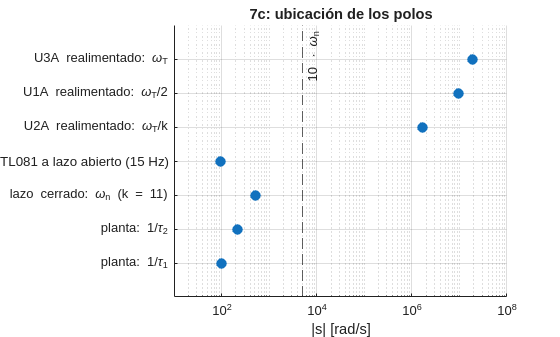


figure
scatter(polos, 1:numel(polos), 60, 'filled'); hold on
xline(10*wn_de(nom), '--', '10 \cdot \omega_n');
set(gca, 'XScale', 'log', 'YTick', 1:numel(polos), 'YTickLabel', nombres7)
ylim([0, numel(polos) + 1]); grid on
xlim([10 1e8])
xlabel('|s| [rad/s]')
title('7c: ubicación de los polos');  guardar("B_7c_polos")

%% 7c (parte 2). ¿En qué condiciones pasa a importar el op-amp?
% Planta + polo de U2A realimentado en p3 = wT/k (los de U1A y U3A están más lejos)
k_barr   = 1:800;
nk       = numel(k_barr);
dom_id   = zeros(nk, 1);       % polo dominante (parte imaginaria > 0), op-amps ideales
dom_tl   = zeros(nk, 1);       % polo dominante con el polo de U2A
routh_ok = true(nk, 1);
wn_barr  = zeros(nk, 1);

for j = 1:nk
    kj = k_barr(j);
    p3 = wT/kj;
    den_id = conv([tau1 1], [tau2 1]) + [0 0 kj];
    den_tl = conv(conv([tau1 1], [tau2 1]), [1/p3 1]) + [0 0 0 kj];

    r_id = roots(den_id);
    r_tl = roots(den_tl);
    [~, i_id] = max(imag(r_id));
    [~, i_tl] = max(imag(r_tl));
    dom_id(j) = r_id(i_id);
    dom_tl(j) = r_tl(i_tl);

    % Routh para a3 s^3 + a2 s^2 + a1 s + a0: estable si a2*a1 > a3*a0
    routh_ok(j) = den_tl(2)*den_tl(3) > den_tl(1)*den_tl(4);
    wn_barr(j) = sqrt((1 + kj)/(tau1*tau2));
end

% Chequeo: el cruce de las raíces tiene que coincidir con Routh
k_crit_num   = k_barr(find(real(dom_tl) > 0, 1));
k_crit_routh = k_barr(find(~routh_ok, 1));
k_crit_aprox = (-1 + sqrt(1 + 4*wT*(tau1 + tau2)))/2;
fprintf('k crítico: raíces = %d | Routh exacto = %d | fórmula aproximada = %.0f\n', k_crit_num, k_crit_routh, k_crit_aprox);

k crítico: raíces = 529 | Routh exacto = 529 | fórmula aproximada = 526


fprintf('En k crítico: zeta (ideal) = %.3f y el polo de U2A está %.1f veces más lejos que wn\n', (tau1 + tau2)/(2*sqrt((1 + k_crit_num)*tau1*tau2)), (wT/k_crit_num)/wn_barr(k_crit_num));

En k crítico: zeta (ideal) = 0.047 y el polo de U2A está 10.6 veces más lejos que wn


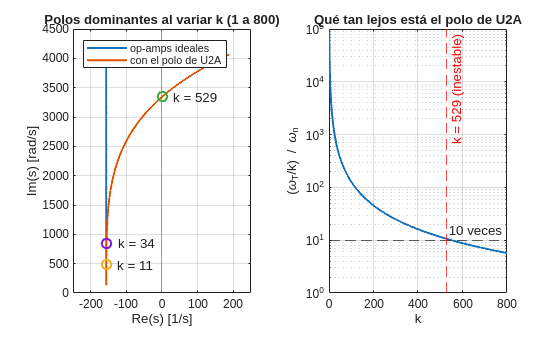


figure
tiledlayout(1, 2)

% Izquierda: recorrido de los polos dominantes al subir k
nexttile
plot(real(dom_id), imag(dom_id), 'LineWidth', 1.5); hold on
plot(real(dom_tl), imag(dom_tl), 'LineWidth', 1.5)
xline(0, 'Color', [0.5 0.5 0.5]);
for kk = [11, 34, k_crit_num]
    plot(real(dom_tl(kk)), imag(dom_tl(kk)), 'o', 'MarkerSize', 7, 'LineWidth', 1.5)
    text(real(dom_tl(kk)), imag(dom_tl(kk)), sprintf('   k = %d', kk))
end
grid on; xlabel('Re(s) [1/s]'); ylabel('Im(s) [rad/s]'); xlim([-250 250])
legend('op-amps ideales', 'con el polo de U2A', 'Location', 'northwest')
title('Polos dominantes al variar k (1 a 800)')

% Derecha: cuántas veces más lejos que wn está el polo de U2A
nexttile
semilogy(k_barr, (wT./k_barr')./wn_barr, 'LineWidth', 1.5); hold on
yline(10, '--', '10 veces');
xline(k_crit_num, 'r--', sprintf('k = %d (inestable)', k_crit_num));
grid on; xlabel('k'); ylabel('(\omega_T/k) / \omega_n')
title('Qué tan lejos está el polo de U2A');  guardar("B_7c_k_critico")


% ---------------------------------------------------------------------
% Funciones auxiliares (en un Live Script tienen que ir al final)
% ---------------------------------------------------------------------
function guardar(nombre)
% Pasa la figura actual a tema claro (fondo blanco) y la guarda en imagenes/
    f = gcf;
    theme(f, "light");
    if ~isfolder("imagenes")
        mkdir("imagenes");
    end
    exportgraphics(f, "imagenes/" + nombre + ".png", "Resolution", 300);
end

function guardar_modelo(modelo, nombre)
% Guarda una imagen del diagrama de Simulink en imagenes/
    if ~isfolder("imagenes")
        mkdir("imagenes");
    end
    print(['-s' modelo], '-dpng', '-r300', ['imagenes/' char(nombre) '.png']);
end